# List of things that need to be added:

- Making plots nice

- Extrapolation length

- Errorbars

- Bugfixing peak position....



clear all
close all
clc


## Loading all the data

First specify the path (single), dates (can be multiple in a cell) and the types of the sample (can be multiple in a cell, make sure that the order overlaps. The dates and sample names are set in a different cell such that it is easier to create for example legends using the sample names. All data is saved in a struct. The exposure times are also automatically imported. The averaging is automatically performed and the Dark measurements are automatically subtracted.


%path='C:\Users\User\OneDrive - Universiteit Twente\Applied physics\AP - Quartile 4\Nanophotonics exp\data\';
%dates={'230614' '230612' '230614' '230612'};
%samples={'C5_r2_p003' 'C5_r2_p006' 'C5_r2_p009' 'C5_r2_p012'};

path='C:\Users\User\OneDrive - Universiteit Twente\Applied physics\AP - Quartile 4\Nanophotonics exp\data\';
dates=  {'230614' '230612' '230614' '230612'};
samples={'C5_r2_p003' 'C5_r2_p006' 'C5_r2_p009' 'C5_r2_p012'};
samplename=extractBefore(samples{1,1},6); %extracts the type of sample
samplename=strrep(samplename, '_', ' '); %to replace underscore with space in the samplename

exposuretimes=zeros(1,4);%preallocating for speed.
numsamples=size(dates,2);
packfracs=zeros(1,numsamples);
for kk=1:numsamples
packfracs(1,kk)=str2double(insertAfter(extractAfter(samples{1,kk},7),1,'.'));
end

for kk=1:numsamples %runs over the number of samples that are filled in
    temp=readcell([path dates{1,kk} '_' samples{1,kk} '\readme.txt']);
    exposuretimes(1,kk)=temp{1,5};
    clear temp
    data.(samples{1,kk}).darkIR=imread([path dates{1,kk} '_' samples{1,kk} '\DarkCount_IR\0.tif']);
    data.(samples{1,kk}).darkLED=imread([path dates{1,kk} '_' samples{1,kk} '\DarkCount_LED\0.tif']);
    for ii=1:20 %based on 20 segments
        vname1=sprintf('top_IR%d',ii); %creates field names
        avgsum=0;
        for jj=1:10

            vname2=sprintf('m%d',jj);
            ii=num2str(ii);
            jj=num2str(jj-1);

            data.(samples{1,kk}).(vname1).(vname2)=imread([path dates{1,kk} '_' samples{1,kk} '\top_IR' ii 'a\' jj '.tif'])-data.(samples{1,kk}).darkIR;
            avgsum=avgsum+data.(samples{1,kk}).(vname1).(vname2)./10;
        end
        data.(samples{1,kk}).(vname1).avg=avgsum;
    end

    for ii=1:20 %based on 20 segments
        vname1=sprintf('top_LED%d',ii);
        avgsum=0;
        for jj=1:10

            vname2=sprintf('m%d',jj);
            ii=num2str(ii);
            jj=num2str(jj-1);

            data.(samples{1,kk}).(vname1).(vname2)=imread([path dates{1,kk} '_' samples{1,kk} '\top_LED' ii 'a\' jj '.tif'])-data.(samples{1,kk}).darkLED;
            avgsum=avgsum+data.(samples{1,kk}).(vname1).(vname2)./10;
        end
        data.(samples{1,kk}).(vname1).avg=avgsum;

    end
end


## Finding the edge

This part of the code finds the edge of the samples using the sobel edge detection in a vertical method. As the edge is close to vertical this gives the best result. The threshold is set in such a way that the edge that is found is close to the real edge, this is a variable that can be changed to obtain better results. THe sensitivity defines how sensitive the edge detection works, putting it to a higher value actually reduces the sensitivity and can lead to no edges being found, lowering it can lead to everything being an edge.

threshold=140

threshold = 140

sensitivity=0.0175

sensitivity = 0.0175

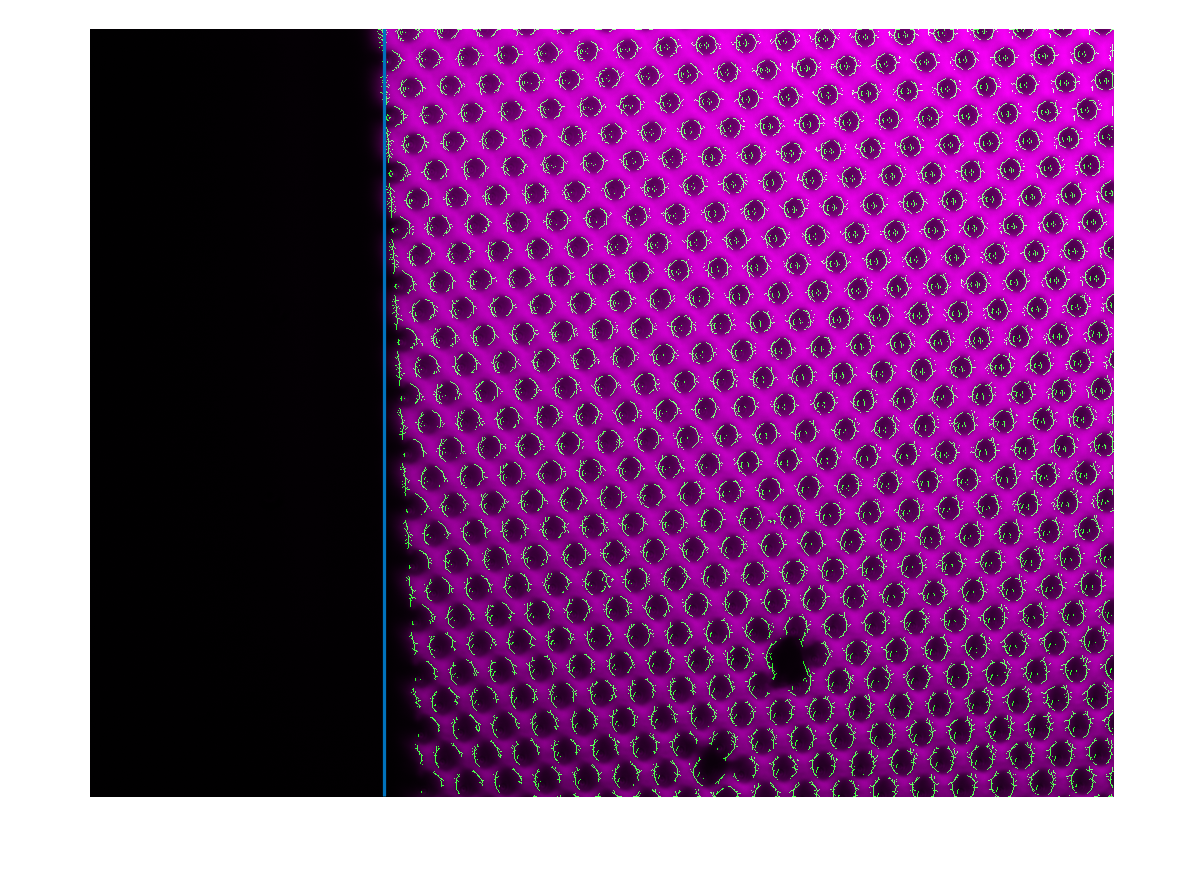

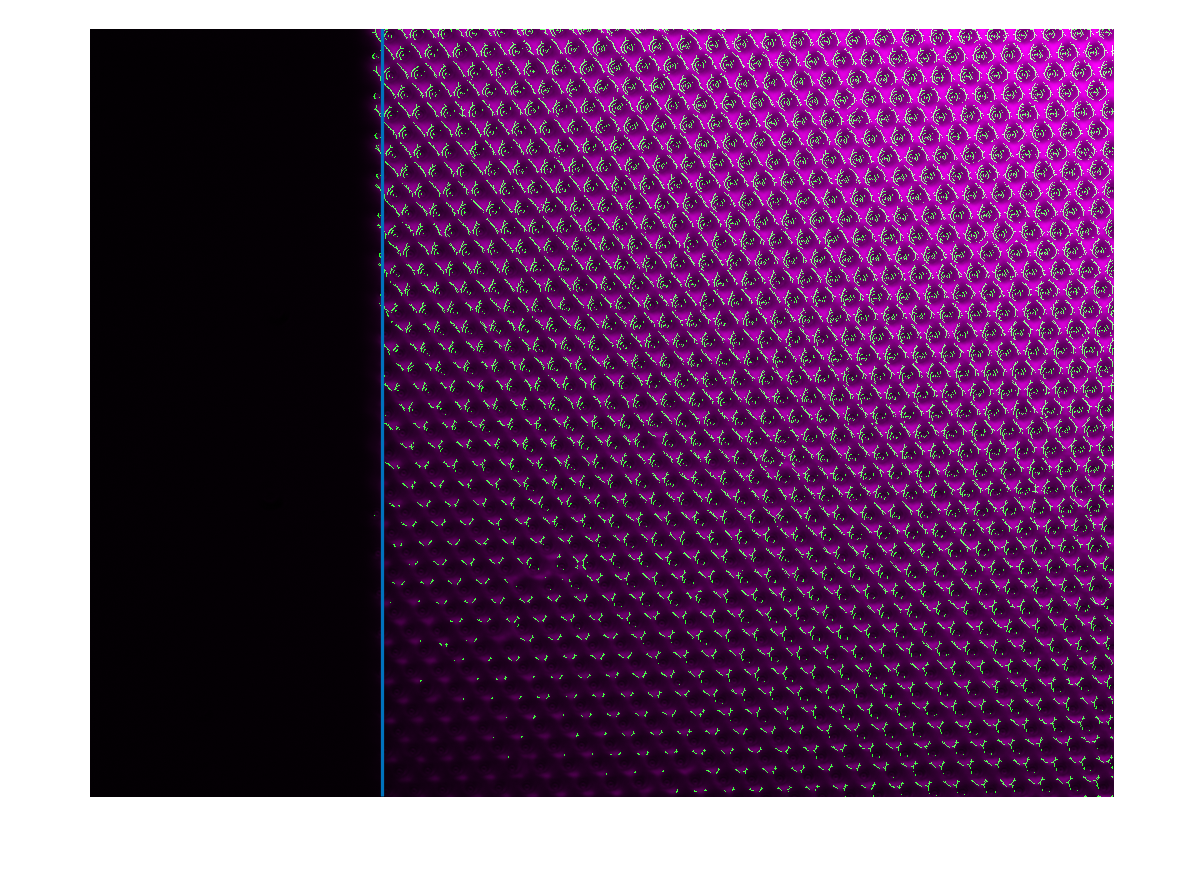

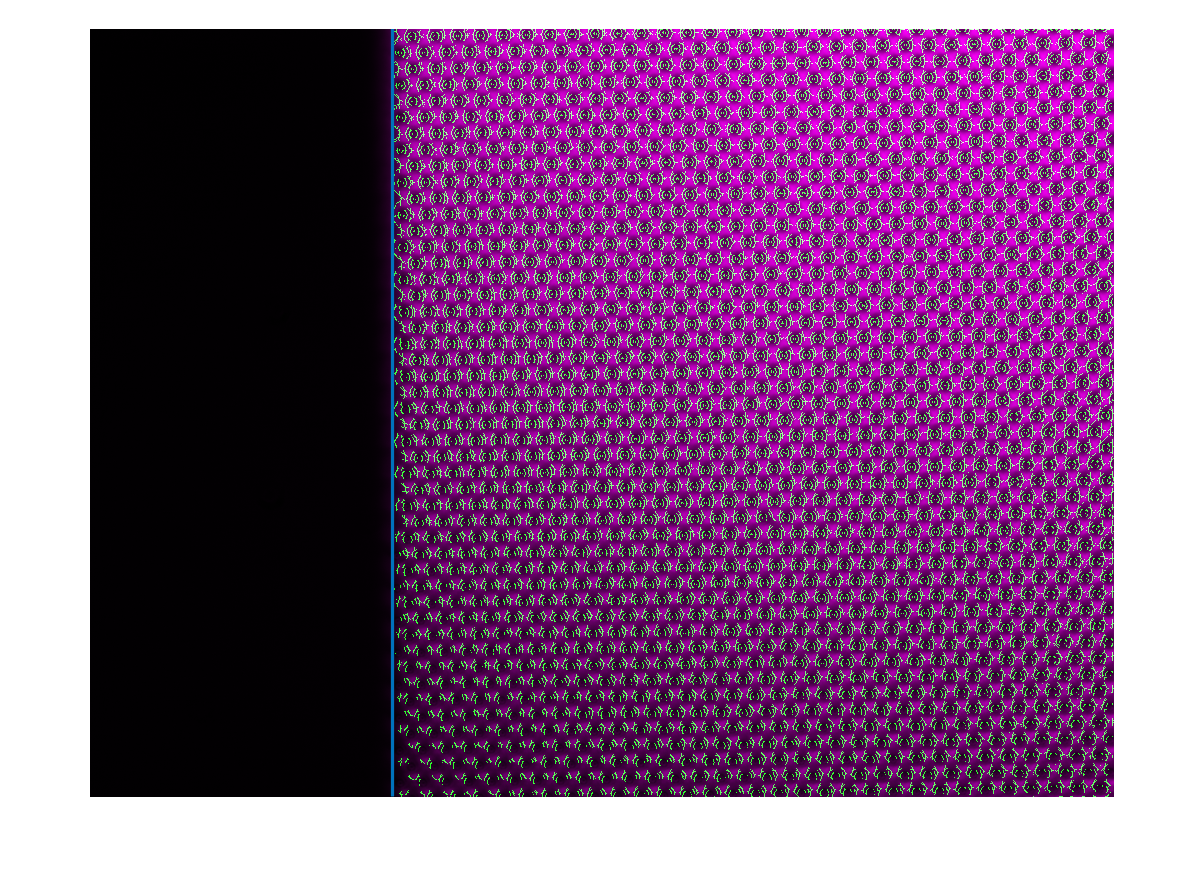

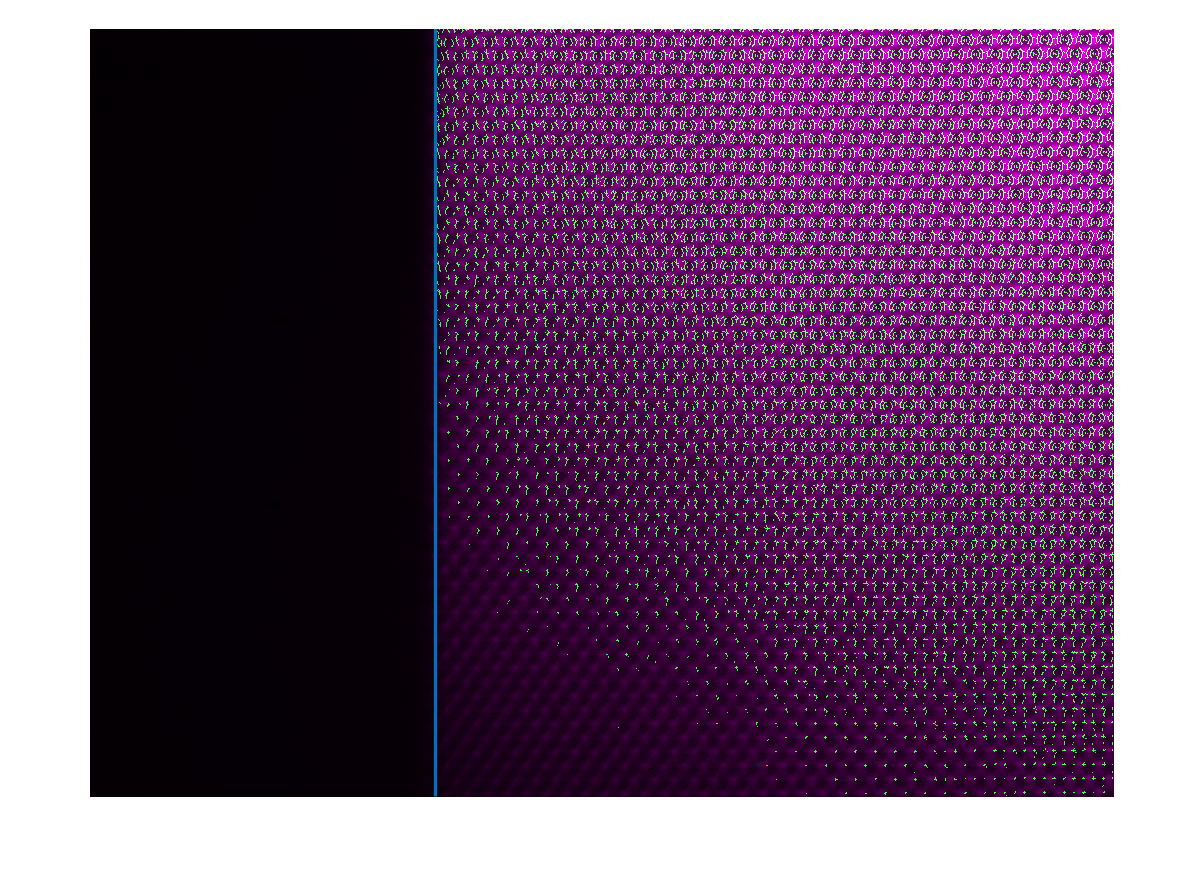

for kk=1:numsamples
    for jj=1:20
        vname1=sprintf('top_LED%d',jj);
        BW=edge(data.(samples{1,kk}).(vname1).avg,'Sobel',sensitivity,'vertical'); %To use the edge function, the image processing toolbox is required

        ii=6;
        while sum(sum(BW(:,ii-2:ii+2)))<threshold
            vedge.(samples{1,kk}).(vname1)=ii; %this is the edge that is found
            ii=ii+1;
            if ii==1021
                break
            end
        end
        if jj==9
            figure
            imshowpair(BW,data.(samples{1,kk}).(vname1).avg);

            %imshow(data.(samples{1,kk}).(vname1).avg)
            x=[vedge.(samples{1,kk}).(vname1),vedge.(samples{1,kk}).(vname1)];
            y=[0 768];
            line(x,y,'LineWidth',2)
        end
    end
end

## Data analysis

This first part of the data analysis takes the sum over the y-axis and makes a plot. Start and end segments can be chosen (usually it is best to look at the middle of the sample). Obviously, it is necessary to choose the startings segment lower than the ending segment... For the rest of the data analysis that follows after, an average is taken over all these segments. 


c=parula(7*numsamples); %preallocating the colors
figure('Name',['yslice' samplename])
hold on
pixsize=1; %find out correct pixel size
x=zeros(size(data.(samples{1,kk}).(vname1).m1,2),1); %preallocating for speed
for ii=1:size(data.(samples{1,kk}).(vname1).m1,2)
    x(ii,1)=ii*pixsize;
end
start=7 %start segment

start = 7

ends=13 %end segment

ends = 13

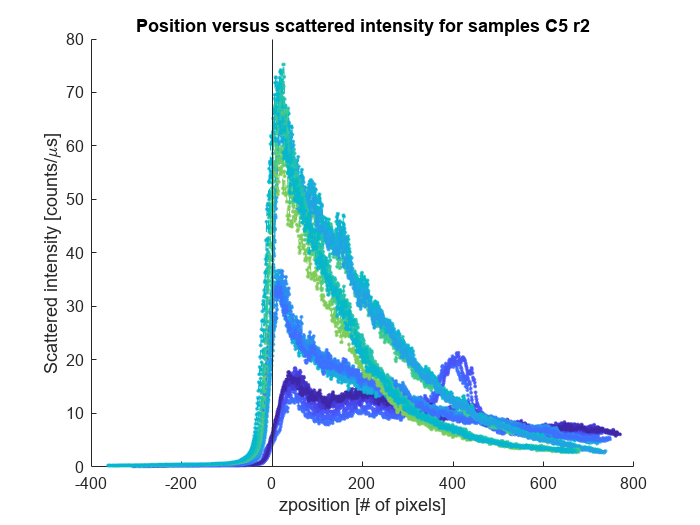

for kk=1:numsamples
    avgintensity.(samples{1,kk})=0;
    avgedge.(samples{1,kk})=0;
    for ii=start:ends
        vname1=sprintf('top_IR%d',ii);
        vname2=sprintf('top_LED%d',ii);
        plot(x-vedge.(samples{1,kk}).(vname2),sum(data.(samples{1,kk}).(vname1).avg)./exposuretimes(1,kk),'--.','color',c(kk*(8-(kk-1))-(ii-6),:))
        %y=ylim; %before 2018
        %plot([vedge.(vname2) vedge.(vname2)],[y(1) y(2)],'--','color',c(ii-6,:)) %before 2018
        %plot([vedge.(vname2) vedge.(vname2)],[y(1) y(2)],'k--')%'color',c(ii,:))
        xline(0)
        %xline(vedge.(samples{1,kk}).(vname2),'color',c(kk*(8-(kk-1))-(ii-6),:)) % after 2018
        avgedge.(samples{1,kk})=avgedge.(samples{1,kk})+vedge.(samples{1,kk}).(vname2)./(ends-start);
        avgintensity.(samples{1,kk})=avgintensity.(samples{1,kk}) + sum(data.(samples{1,kk}).(vname1).avg)./exposuretimes(1,kk)./(ends-start);
    end
end
title(['Position versus scattered intensity for samples ' samplename])
xlabel('zposition [# of pixels]')
ylabel('Scattered intensity [counts/\mus]')

## Finding the peaks and slope of decay after peak

Here we find the peakvalue, its position and the slope of the decay after the peak for each of the samples. A seperate plot is made for each

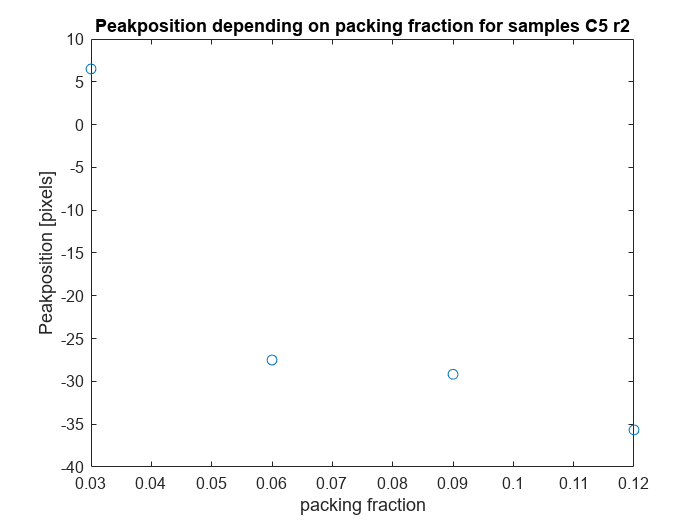

maxintens=zeros(1,numsamples); %preallocating for speed
intenspos=zeros(1,numsamples); %preallocating for speed
decslope=zeros(1,numsamples); %preallocating for speed
for kk=1:numsamples
    [M,I]=max(avgintensity.(samples{1,kk})); %finding the peakvalue (M) and its position (I)
    maxintens(1,kk)=M;
    intenspos(1,kk)=I-avgedge.(samples{1,kk});
    temp=fit(x(I+5:I+25,1),transpose(avgintensity.(samples{1,kk})(1,I+5:I+25)),'poly1'); %making a linear fit to the decay
    decslope(1,kk)=temp.p1;
end
figure
plot(packfracs,intenspos,'o') %seems bugged, please check
title(['Peakposition depending on packing fraction for samples ' samplename])
xlabel('packing fraction')
ylabel('Peakposition [pixels]')

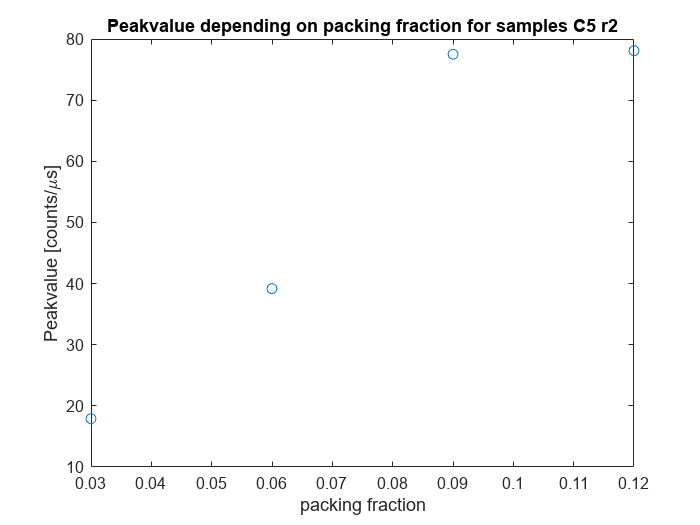

figure
plot(packfracs,maxintens,'o')
title(['Peakvalue depending on packing fraction for samples ' samplename])
xlabel('packing fraction')
ylabel('Peakvalue [counts/\mus]')

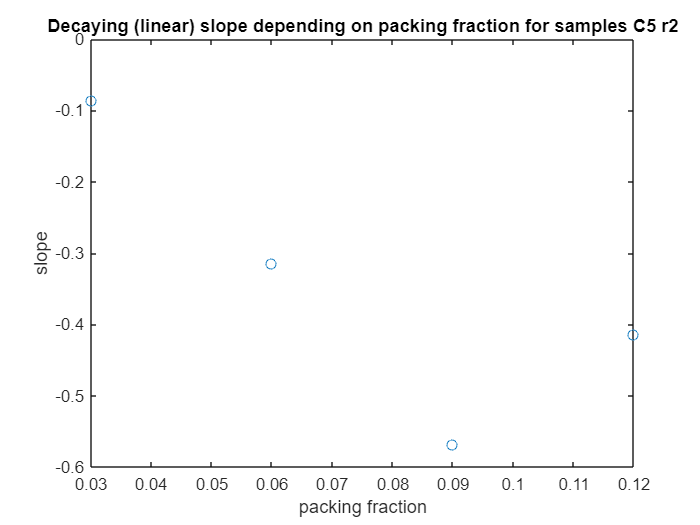

figure
plot(packfracs,decslope,'o')
xlabel('packing fraction')
ylabel('slope')
title(['Decaying (linear) slope depending on packing fraction for samples ' samplename])

## Integral under curve

Here we integrate all the data over the entire z range to obtain the total upward scattered intensity by the sample

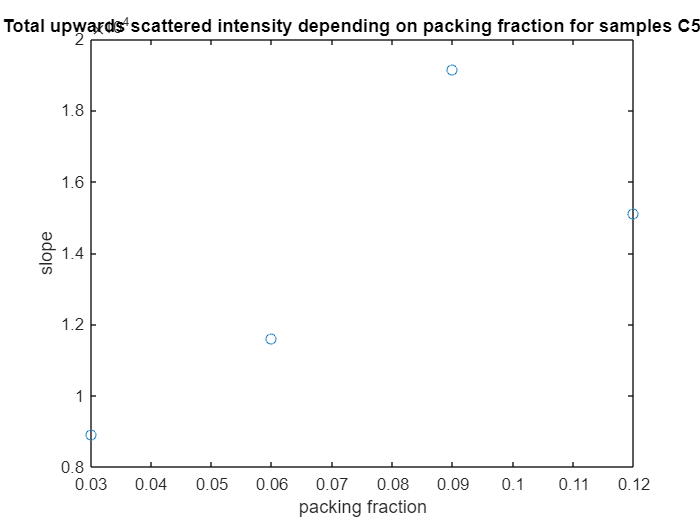

integ=zeros(1,numsamples); %preallocating for speed
for kk=1:numsamples
    integ(1,kk)=trapz(x,avgintensity.(samples{1,kk})); %integrating over the entire z range
end
figure
plot(packfracs,integ,'o')
xlabel('packing fraction')
ylabel('slope')
title(['Total upwards scattered intensity depending on packing fraction for samples ' samplename])